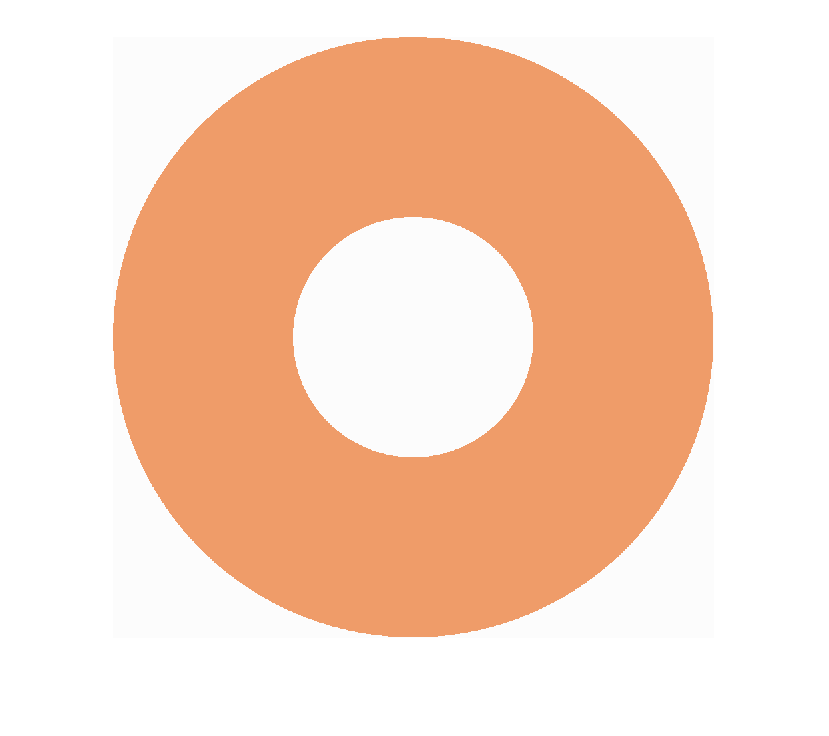

pearl = drawPearl2(901, [240, 157, 105]/256, 0.99);
imshow(pearl)

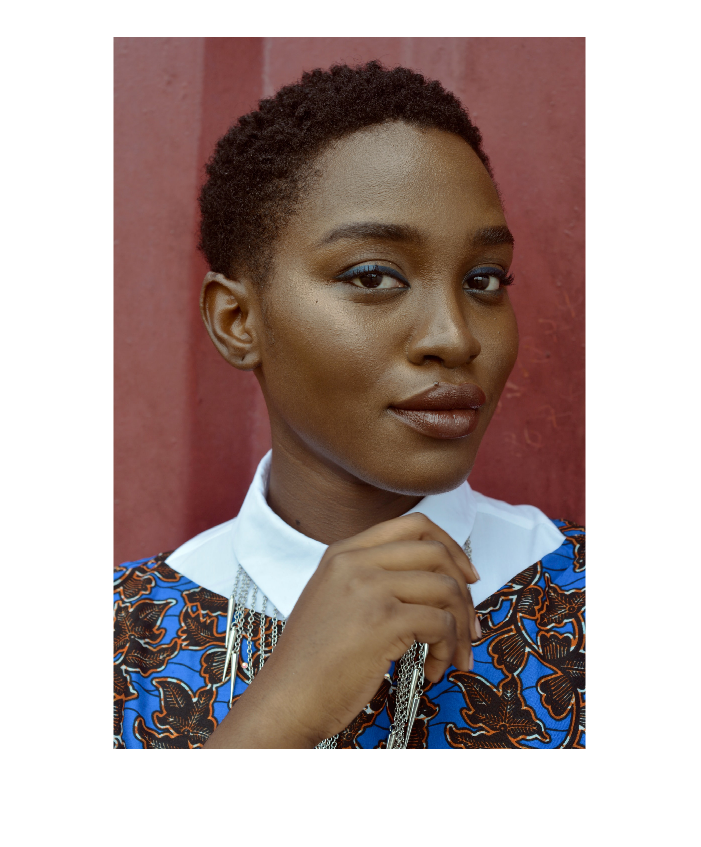

% ------ Original Image ------ 
im = imread('.\images\prince-akachi.jpg');
im_size = size(im); % Check size of image
pearl_size = 31; % Diameter of the pearl
% Not the whole iamage, so the image and reproduced image will be the same size
% dependent on the pearl diamter
im2 = im(1:floor(im_size(1)/pearl_size)*pearl_size, 1:floor(im_size(2)/pearl_size)*pearl_size,:);
imshow(im2)

% ------ Reproduce it to pearls ------ 
% Set the background color behind the pearls
% Dont set the color to 1, cause then the code won't work!
b_color = 0.3;
% Color spectrum:
% 1. HTML colors
% 2. Optimised HTML colors
% 3. Randomised Colors
% 4. Colors dependent on the image 

% --- HTML COLORS ---
o_color = 1; % Color option
rep_image_1 = drawMultiplePearls2(im2, pearl_size,b_color, o_color);
output1 = qualityMeasures(im2double(im2),rep_image_1); % Testing image

SNR1: 0.89758
Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...
S_CIELAB1: 0.91667
SSIM: 0.44088


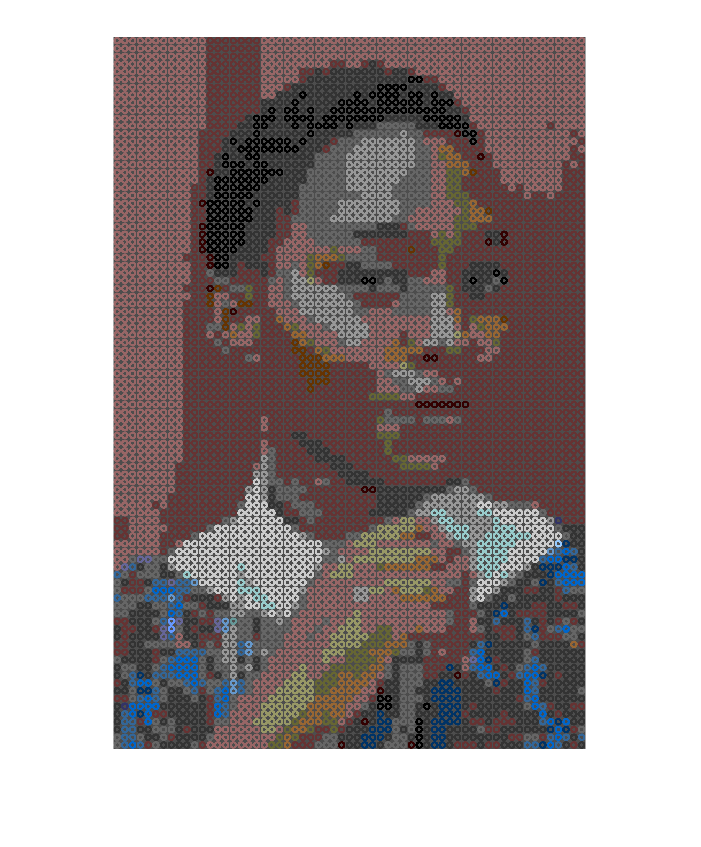

imshow(rep_image_1)

% --- OPTIMISED HTML COLORS ---
o_color = 2; % Color option
rep_image_2 = drawMultiplePearls2(im2, pearl_size,b_color, o_color);
output2 = qualityMeasures(im2double(im2),rep_image_2); % Testing image

SNR1: 0.46931
Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...
S_CIELAB1: 1.163
SSIM: 0.22531


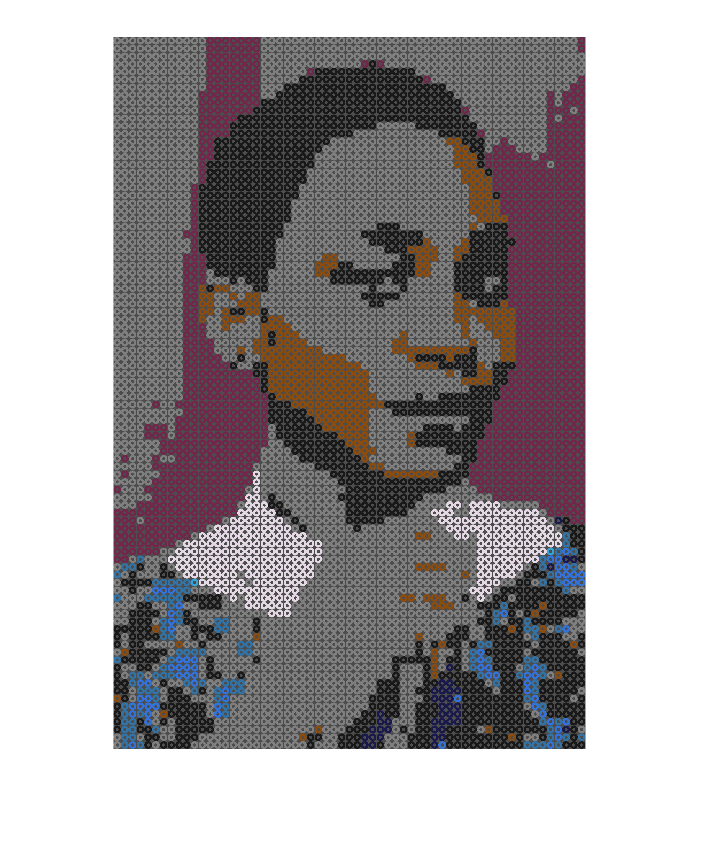

imshow(rep_image_2)

% --- RANDOM COLORS ---
o_color = 3; % Color option
rep_image_3 = drawMultiplePearls2(im2, pearl_size,b_color, o_color);
output3 = qualityMeasures(im2double(im2),rep_image_3); % Testing image

SNR1: 1.6835
Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...
S_CIELAB1: 1.0102
SSIM: 0.52824


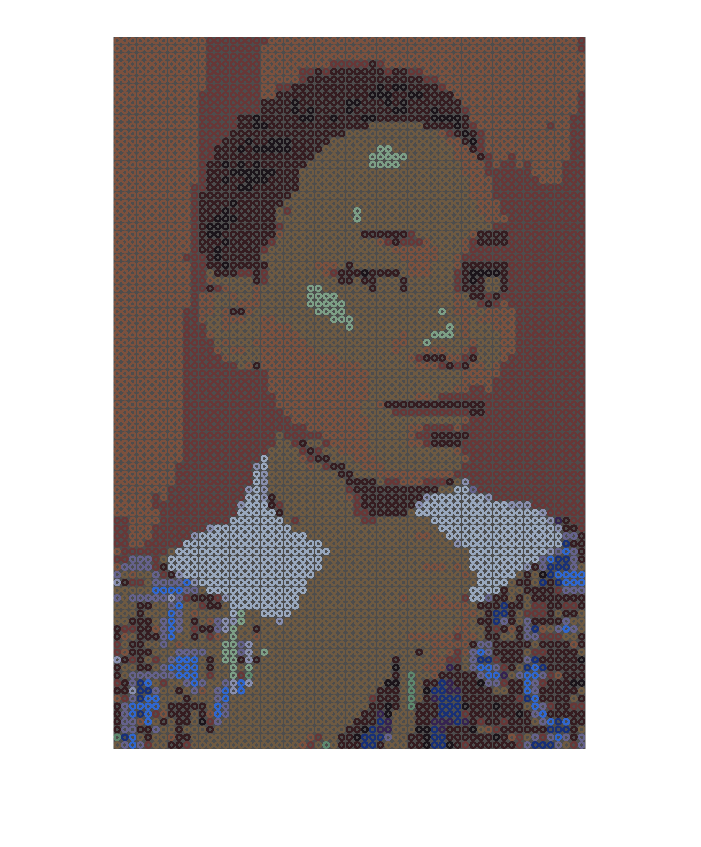

imshow(rep_image_3)

% --- COLORS FROM IMAGE ---
o_color = 4; % Color option
rep_image_4 = drawMultiplePearls2(im2, pearl_size,b_color, o_color);
output4 = qualityMeasures(im2double(im2),rep_image_4); % Testing image

SNR1: 1.068
Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...
S_CIELAB1: 0.78129
SSIM: 0.53478


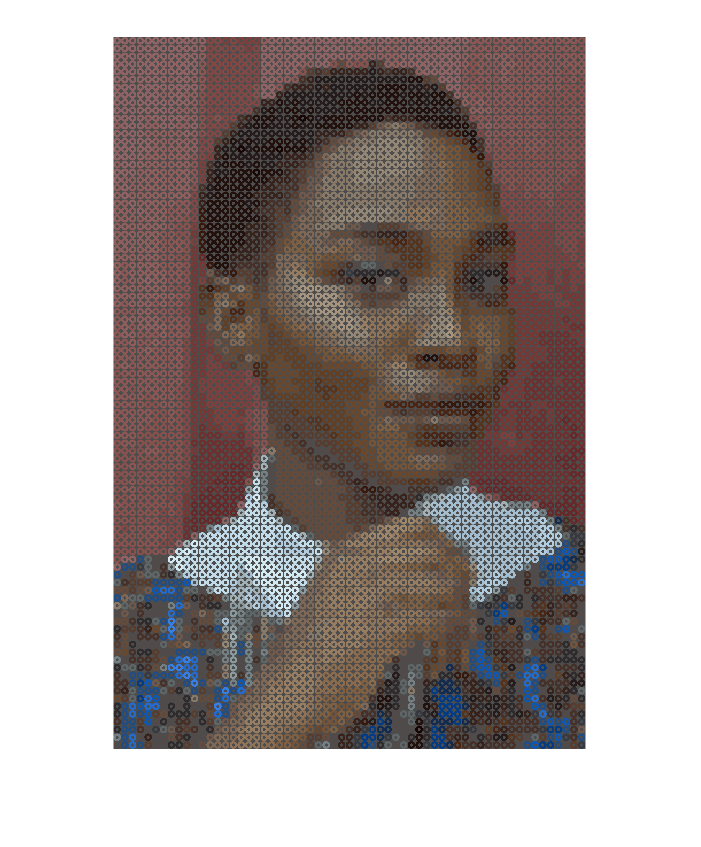

imshow(rep_image_4)